VALETTE Hervé et LÉONARD Tristan

## TP VERTÈBRE

clc
clear all
close

`PARTIE 1 - AFFICHAGE MODÈLES VERTÈBRE ET POINTS DES PLATEAUX`

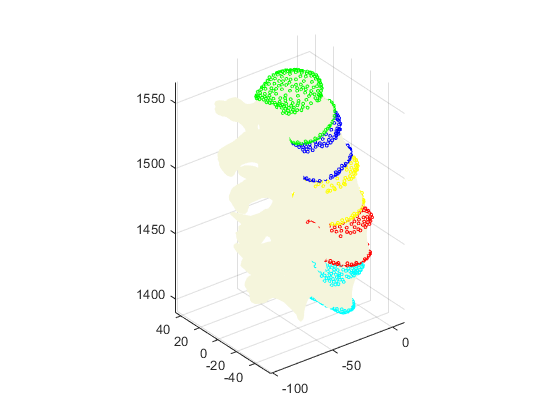

couleur = ["green", "blue", "yellow", "red", "cyan"];   % Chaque couleur sera associée à une vertèbre

for nv = 1:5 % nv = numéro vertèbre
    % Lecture fichiers
    nom_fichier_wrl = sprintf('Vertebre_L%d.wrl', nv);
    nom_fichier_ddr = sprintf('Vertebre_L%d.ddr', nv);
    
    modele3D_v{nv} = lire_fichier_vrml(nom_fichier_wrl);
    region_v{nv} = lire_fichier_ddr(nom_fichier_ddr);
    region_v{nv} = RegtyI2tyII(region_v{nv});
    
    % Affichage points plateau supérieur de la vertèbre
    polygones_voulu_v{nv} = region_v{nv}.plat_sup.Noeuds;
    for i = 1:length(polygones_voulu_v{nv}) % Pour chaque polygone (i)
        % Récupération coordonnées points
        noeud_voulu = modele3D_v{nv}.Polygones(polygones_voulu_v{nv}(i),:);
        points = modele3D_v{nv}.Noeuds(noeud_voulu(1),:);
        
        % Affichage points
        scatter3(points(:,1), points(:,2), points(:,3), 5, couleur(nv));
        hold on
    end
    
    % Affichage points plateau inférieur de la vertèbre
    polygones_voulu_v{nv} = region_v{nv}.plat_inf.Noeuds;
    for i = 1:length(polygones_voulu_v{nv}) % Pour chaque polygone (i)
        % Récupération coordonnées points
        noeud_voulu = modele3D_v{nv}.Polygones(polygones_voulu_v{nv}(i),:);
        points = modele3D_v{nv}.Noeuds(noeud_voulu(1),:);
        
        % Affichage points
        scatter3(points(:,1), points(:,2), points(:,3), 5, couleur(nv));
        hold on
    end
    
    % Affichage vertèbres
    DisplayMesh(modele3D_v{nv}.Noeuds, modele3D_v{nv}.Polygones, '#f5f5dc');
    hold on
end
hold off

clc
clear all
close

`Partie 2 - CALCUL HAUTEUR DES DISQUES`

On considère cette hauteur comme la distance entre les points du plateau inférieur d'une vertèbre au dessous et les points du plateau supérieur d'une vertèbre en dessous

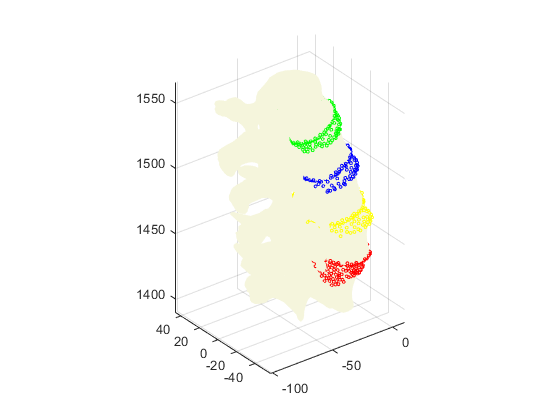

couleur = ["green", "blue", "yellow", "red"]; % Chaque couleur sera associée à une hauteur de disque
x_inf = []; y_inf = []; z_inf = [];
x_sup = []; y_sup = []; z_sup = [];
distances = [];
nd = 1; % nd = numéro disque

for nv = 2:5 % nv = numéro vertèbre
    % Lecture fichiers vertèbre AU DESSUS pour points PLATEAU INFÉRIEUR (sauf dernier)
    nom_fichier_wrl = sprintf('Vertebre_L%d.wrl', nv-1);
    nom_fichier_ddr = sprintf('Vertebre_L%d.ddr', nv-1);
    
    modele3D_v{nv-1} = lire_fichier_vrml(nom_fichier_wrl);
    region_v{nv-1} = lire_fichier_ddr(nom_fichier_ddr);
    region_v{nv-1} = RegtyI2tyII(region_v{nv-1});
    
    % Pour chaque polygone (i) d'une vertèbre, on récupère les coordonnées xyz des points puis on les affiche
    polygones_voulu_v{nv-1} = region_v{nv-1}.plat_inf.Noeuds;
    for i = 1:length(polygones_voulu_v{nv-1})
        noeud_voulu = modele3D_v{nv-1}.Polygones(polygones_voulu_v{nv-1}(i),:);
        point_inf = modele3D_v{nv-1}.Noeuds(noeud_voulu(1),:);
        x_inf(i) = point_inf(:,1);
        y_inf(i) = point_inf(:,2);
        z_inf(i) = point_inf(:,3);
        
        % Affichage points
        scatter3(point_inf(:,1), point_inf(:,2), point_inf(:,3), 5, couleur(nd));
        hold on
    end
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    % Lecture fichiers vertèbre AU DESSOUS pour points PLATEAU SUPÉRIEUR (sauf premier)
    nom_fichier_wrl = sprintf('Vertebre_L%d.wrl', nv);
    nom_fichier_ddr = sprintf('Vertebre_L%d.ddr', nv);
    
    modele3D_v{nv} = lire_fichier_vrml(nom_fichier_wrl);
    region_v{nv} = lire_fichier_ddr(nom_fichier_ddr);
    region_v{nv} = RegtyI2tyII(region_v{nv});
    
    % Pour chaque polygone (i) d'une vertèbre, on récupère les coordonnées xyz des points puis on les affiche
    polygones_voulu_v{nv} = region_v{nv}.plat_sup.Noeuds;
    for i = 1:length(polygones_voulu_v{nv})
        noeud_voulu = modele3D_v{nv}.Polygones(polygones_voulu_v{nv}(i),:);
        point_sup = modele3D_v{nv}.Noeuds(noeud_voulu(1),:);
        x_sup(i) = point_sup(:,1);
        y_sup(i) = point_sup(:,2);
        z_sup(i) = point_sup(:,3);
        
        % Affichage points
        scatter3(point_sup(:,1), point_sup(:,2), point_sup(:,3), 5, couleur(nd));
        hold on
    end
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    % Calcul distances
    qte = min(length(x_sup), length(x_inf)); % Car deux vertèbres n'ont pas forcément le même nombre de points
    for i = 1:qte
        distances(i) = norm([x_sup(i)-x_inf(i), y_sup(i)-y_inf(i), z_sup(i)-z_inf(i)]);
    end
    minimum{nd} = min(distances);
    maximum{nd} = max(distances);
    moyenne{nd} = mean(distances);
    
    % Affichage vertèbres
    if (nd == 1) % On affiche d'abord la première vertèbre
        DisplayMesh(modele3D_v{nv-1}.Noeuds, modele3D_v{nv-1}.Polygones, '#f5f5dc');
        hold on
    end
    DisplayMesh(modele3D_v{nv}.Noeuds, modele3D_v{nv}.Polygones, '#f5f5dc');
    hold on
    
    nd =  nd+1;
end
hold off


% Affichage valeurs hauteurs
minimum

minimum = 1×4 cell array
    {[6.5249]}    {[3.8416]}    {[9.1381]}    {[5.2375]}


maximum

maximum = 1×4 cell array
    {[48.4538]}    {[50.4385]}    {[54.7484]}    {[55.3568]}


moyenne

moyenne = 1×4 cell array
    {[22.3690]}    {[22.6325]}    {[29.2303]}    {[24.1323]}


clc
clear all
close

`Partie 3 - CALCUL ORIENTATION PLATEAUX DES VERTÈBRES`

On considère :

Orientation plan moyen plateau sup = Orientation plan moyen plateau inf = Orientation plateaux d'une vertèbre

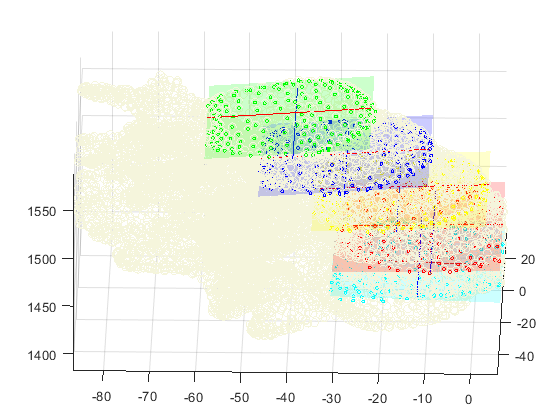

couleur = ["green", "blue", "yellow", "red", "cyan"];   % Chaque couleur sera associée à un plan médian

for nv = 1:5 % nv = numéro vertèbre
    % Lecture fichiers
    nom_fichier_wrl = sprintf('Vertebre_L%d.wrl', nv);
    nom_fichier_ddr = sprintf('Vertebre_L%d.ddr', nv);
    
    modele3D_v{nv} = lire_fichier_vrml(nom_fichier_wrl);
    region_v{nv} = lire_fichier_ddr(nom_fichier_ddr);
    region_v{nv} = RegtyI2tyII(region_v{nv});
    
    % Pour chaque polygone (i) d'une vertèbre, on récupère les coordonnées xyz des points puis on les affiche
    polygones_voulu_v{nv} = region_v{nv}.plat_sup.Noeuds;
    x = []; y = []; z = [];
    
    for i = 1:length(polygones_voulu_v{nv})
        noeud_voulu = modele3D_v{nv}.Polygones(polygones_voulu_v{nv}(i),:);
        points = modele3D_v{nv}.Noeuds(noeud_voulu(1),:);
        x(i) = points(:,1);
        y(i) = points(:,2);
        z(i) = points(:,3);
        
        % Affichage points
        scatter3(points(:,1), points(:,2), points(:,3), 5, couleur(nv));
        hold on
    end
    
    % Calcul plan moyen des points du plateau supérieur de la vertèbre
    nb_points = length(z); % Marche aussi pour length(x) et length(y)
    
    A = [x; y; ones(1, nb_points)]*[x; y; ones(1, nb_points)]';
    B = [x; y; ones(1, nb_points)]*z';
    C = A\B;
    
    [X,Y] = meshgrid(min(x):max(x), min(y):max(y));
    Z = C(1)*X + C(2)*Y + C(3);
    
    % Affichage plan moyen des points du plateau supérieur de la vertèbre
    PlanM = surf(X,Y,Z,'FaceAlpha', 0.2, 'facecolor',couleur(nv), 'EdgeColor','none');
    hold on

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    % ORIENTATION AXE X
    % Calcul orientation axe x du plan moyen plateau (bleu) par rapport à 'axe_x' (noir) du référentiel terrestre
%     axe_x = xline(mean(x));  % (AIDE VISUALISATION UNIQUEMENT. Équivalent utilisé dans calcul est le vecteur [0 1 0])
%     hold on
    
    % Récupération des points A et B du plan moyen formant le vecteur au bord du plan moyen selon l'axe x
    [m,n] = size(PlanM.XData);
    Point_A_plan = [PlanM.XData(1,1), PlanM.YData(1,1), PlanM.ZData(1,1)]; % Coin "bas droite"
    Point_B_plan = [PlanM.XData(m,1), PlanM.YData(m,1), PlanM.ZData(m,1)]; % Coin "bas gauche"
    
    % Visualisation points A et B (AIDE VISUALISATION UNIQUEMENT)
%     plot3(Point_A_plan(1), Point_A_plan(2), Point_A_plan(3), 'Marker','*', 'Color','blue', 'MarkerSize',5)
%     plot3(Point_B_plan(1), Point_B_plan(2), Point_B_plan(3), 'Marker','*', 'Color','blue', 'MarkerSize',5)
%     hold on

    % Calcul projeté vecteur AB
    Vecteur_plan_x = [0, Point_B_plan(2)-Point_A_plan(2), Point_B_plan(3)-Point_A_plan(3)];
    
    % Affichage projeté vecteur AB
    line([mean(x) mean(x)], [Point_B_plan(2) Point_A_plan(2)], [Point_B_plan(3) Point_A_plan(3)], 'Color','blue');
    
    % Calcul de l'angle obtenu entre vecteur du plan médian selon x et axe x de référentiel terrestre
    Angle_x_v{nv} = acos(dot(Vecteur_plan_x, [0 1 0])./(dot(norm(Vecteur_plan_x), norm([0 1 0])))).*180./pi;
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    % ORIENTATION AXE Y
    % Calcul orientation axe y du plan moyen plateau (rouge) par rapport à 'axe_y' (noir) du référentiel terrestre
%     axe_y = yline(mean(y)); % (AIDE VISUALISATION UNIQUEMENT. Équivalent utilisé dans calcul est le vecteur [0 1 0])
%     hold on
    
    % Récupération des points A et C du plan moyen formant le vecteur au bord du plan moyen selon l'axe y
    [m,n] = size(PlanM.XData);
    Point_A_plan = [PlanM.XData(1,1), PlanM.YData(1,1), PlanM.ZData(1,1)]; % Coin "bas droite"
    Point_C_plan = [PlanM.XData(1,n), PlanM.YData(1,n), PlanM.ZData(1,n)]; % Coin "haut droite"
    
    % Visualisation points A et C (AIDE VISUALISATION UNIQUEMENT)
%     plot3(Point_A_plan(1), Point_A_plan(2), Point_A_plan(3), 'Marker','*', 'Color','red', 'MarkerSize',5)
%     plot3(Point_C_plan(1), Point_C_plan(2), Point_C_plan(3), 'Marker','*', 'Color','red', 'MarkerSize',5)
%     hold on

    % Calcul projeté vecteur AC
    Vecteur_plan_y = [Point_C_plan(1)-Point_A_plan(1), 0, Point_C_plan(3)-Point_A_plan(3)];
    
    % Affichage projeté vecteur AC
    line([Point_C_plan(1) Point_A_plan(1)], [mean(y) mean(y)], [Point_C_plan(3) Point_A_plan(3)],'Color','red');
    hold on
    
    % Calcul de l'angle obtenu entre vecteur du plan médian selon y et axe y de référentiel terrestre
    Angle_y_v{nv} = acos(dot(Vecteur_plan_y, [1 0 0])./(dot(norm(Vecteur_plan_y), norm([1 0 0])))).*180./pi;
    
    % Affichage vertèbres
    % scatter3 est ici utilisé au lieu de DisplayMesh pour mieux voir les plans et leurs axes sur la figure
%     DisplayMesh(modele3D_v{nv}.Noeuds, modele3D_v{nv}.Polygones,'#f5f5dc');
    scatter3(modele3D_v{nv}.Noeuds(:,1), modele3D_v{nv}.Noeuds(:,2), modele3D_v{nv}.Noeuds(:,3), 'MarkerEdgeColor','#f5f5dc'); 
    hold on
end
hold off


% Affichage des angles obtenus
Angle_x_v

Angle_x_v = 1×5 cell array
    {[4.8231]}    {[5.9070]}    {[3.2322]}    {[0.9267]}    {[3.0615]}


Angle_y_v

Angle_y_v = 1×5 cell array
    {[17.2993]}    {[16.7376]}    {[8.2056]}    {[3.2895]}    {[8.6963]}
